**Draw Average of X(T) Process**

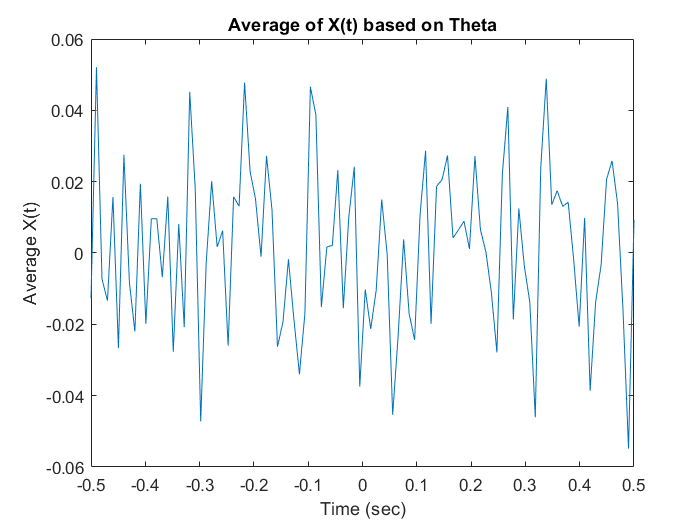

W = 5*pi; 
t_min = -0.5; 
t_max = 0.5;
N = 100; 
theta_length = 100000; 

t = linspace(t_min, t_max, N);

time_theta_matrix = zeros(N, theta_length);
for i = 1:N
    theta = normrnd(0, 2*pi, [1, theta_length]);
    time_theta_matrix(i, :) = theta;
end

X = 10 * cos(W * t' + time_theta_matrix);

average_X = mean(X, 2);

plot(t, average_X);
xlabel('Time (sec)');
ylabel('Average X(t)');
title('Average of X(t) based on Theta');

**Autocorellation of X(T) Process**

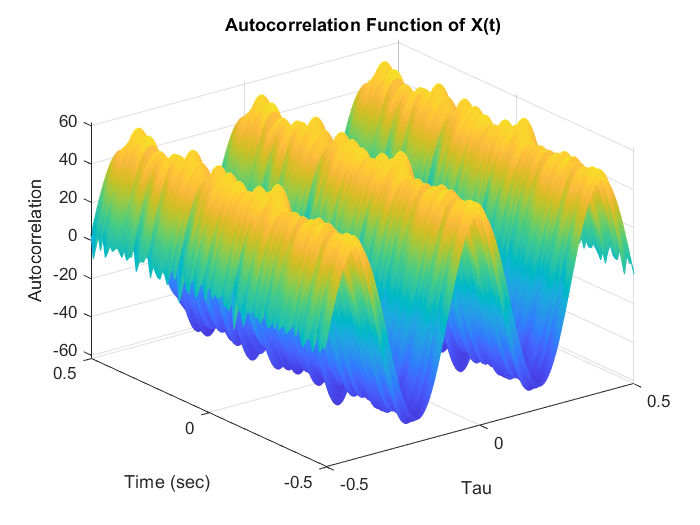


tau = linspace(-t_max, t_max, 2*theta_length-1);

R_X = zeros(100, 2*theta_length - 1);
for i = 1:100
    R_X(i, :) = mean(10 .* cos(time_theta_matrix(:, i) + W .* t(i)) .* 10 .* cos(time_theta_matrix(:, i) + W .* (t(i) + tau)));
end

figure;
mesh(tau, t, R_X);
xlabel('Tau');
ylabel('Time (sec)');
zlabel('Autocorrelation');
title('Autocorrelation Function of X(t)');

**Stationary Process**

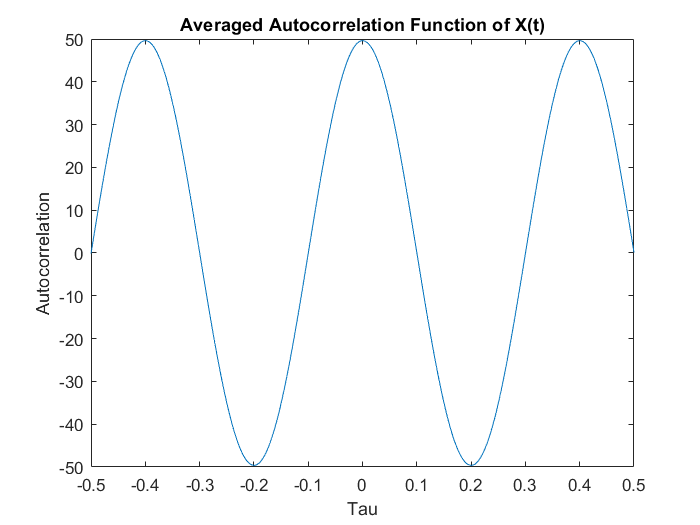

avg_autocorr_X = mean(R_X);

tau = linspace(-t_max, t_max, 2*theta_length-1);

figure;
plot(tau, avg_autocorr_X);
xlabel('Tau');
ylabel('Autocorrelation');
title('Averaged Autocorrelation Function of X(t)');

**Check With Theoriem Calculations**

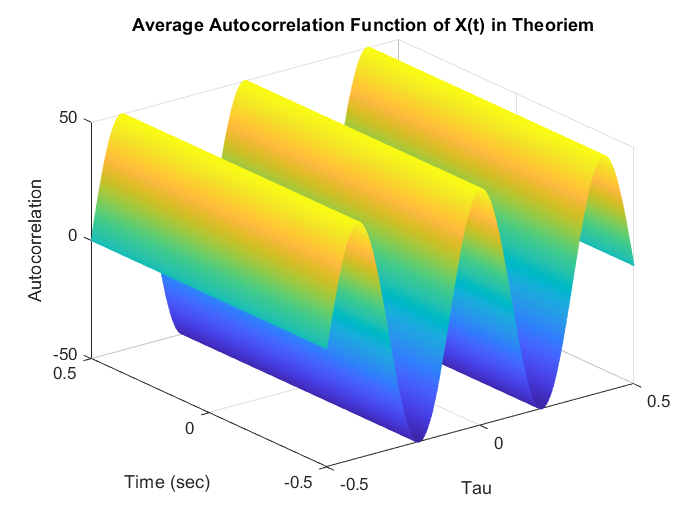

W = 5*pi; 
t_min = -0.5;
t_max = 0.5; 
N = 100; 
theta_length = 100000; 

t = linspace(t_min, t_max, N);
tau = linspace(-t_max, t_max, 2*theta_length-1);

Rx_tau = zeros(N, 2*theta_length - 1);

i = 0;
for k = t
    i = i + 1;
    j = 0;
    for f = tau 
        j = j+1;
        Rx_tau(i, j) = 50 * cos(5 * pi * f);
    end
end
mean_X_T = zeros(1, 100);
figure;
mesh(tau, t, Rx_tau);
xlabel('Tau');
ylabel('Time (sec)');
zlabel('Autocorrelation');
title('Average Autocorrelation Function of X(t) in Theoriem');

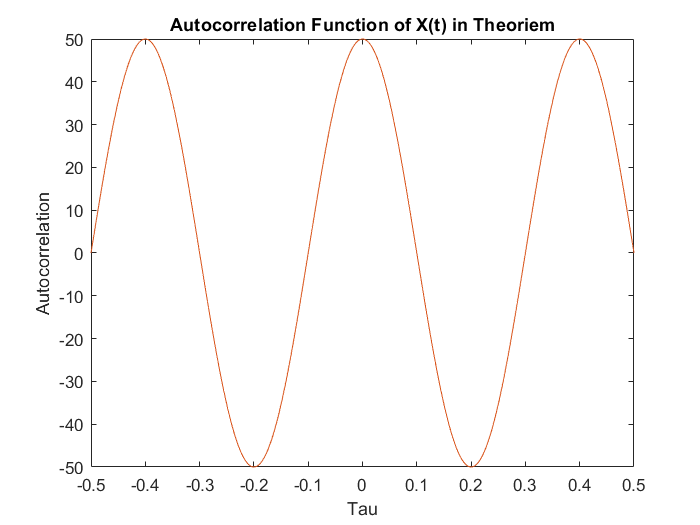


figure;
plot(tau, Rx_tau);
xlabel('Tau');
ylabel('Autocorrelation');
title('Autocorrelation Function of X(t) in Theoriem');

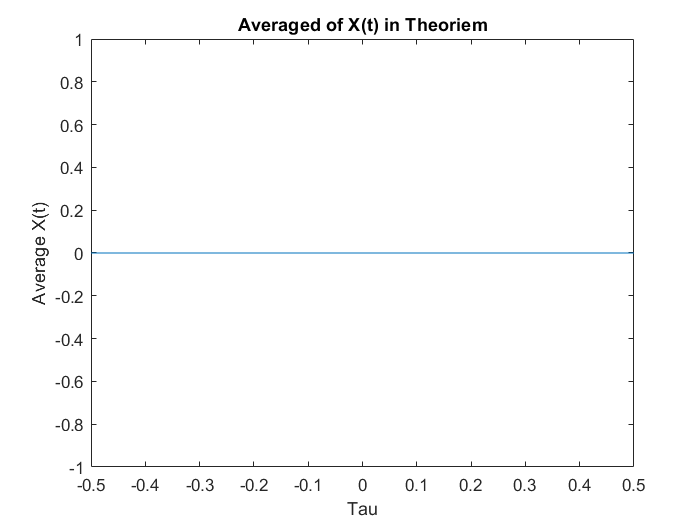


figure;
plot(t, mean_X_T);
xlabel('Tau');
ylabel('Average X(t)');
title('Averaged of X(t) in Theoriem');